# **Ηχογραφημένο Αρχείο**

Επαναλαμβάνουμε την διαδικασία που ακολουθήθηκε στην άσκηση 4 για το ηχογραφημένο αρχείο αυτή τη φορά με τη διαφορά, όμως, ότι δεν προσθέτουμε επιπλέον θόρυβο.

Αρχικά, έχοντας πραγματοποιήσει την δική μας ηχογράφηση εισάγουμε το αρχείο ήχου:

% Use the following to record from mic
% deviceReader = audioDeviceReader;
% setup(deviceReader)
% fileWriter = dsp.AudioFileWriter('my_audio.wav','FileFormat','WAV');
% disp('Speak into microphone now.')
% tic
% while toc < 10
%     acquiredAudio = deviceReader();
%     fileWriter(acquiredAudio);
% end
% disp('Recording complete.')
% release(deviceReader)
% release(fileWriter)

[x,Fs] = audioread('my_audio.wav');
soundsc(x,44100);

Έπειτα, χωρίζουμε το θορυβώδες σήμα σε frames:

X = frame_wind(x,256,0.5);
dim_X = size(X);

Υπολογίζουμε τον FFT κάθε frame και βρίσκουμε το μέτρο και τη γωνία του:

% Find FFT matrix of X
fft_mat = fft(X);
dim_fft = size(fft_mat);

% Find Measure and phase
measure = abs(fft_mat);
phase = angle(fft_mat);

Υπολογίζουμε την ενέργεια κάθε frame και βρίσκουμε τη μέγιστη ενέργεια:

% Find the energy of each frame
abs_fft_mat = abs(fft_mat);
squared_abs_fft_mat = abs_fft_mat.^2;
dim = size(squared_abs_fft_mat);
E = sum(squared_abs_fft_mat);
dim_E = size(E);

% Find Max Energy 
max_energy = max(E);

Επιλέγουμε την τεχνική που θέλουμε για να κάνουμε την εκτίμηση του θορύβου Ν(f) και καλούμε την συνάρτηση determine_noise για να μας επιστρέψει την εκτίμηση του θορύβου

% Run for all values of technique(technique=2,3,4)
technique = 3;
noise = determine_noise(technique,X,measure,E,max_energy);

Στη συνέχεια, αφαιρούμε το θόρυβο από το μέτρο κάθε frame:

measure = denoise(technique,X,measure,E,max_energy,noise);

Στο επόμενο βήμα, ανασυνθέτουμε τον FFT του σήματος:

% Reconstruct FFT from measure and phase
X_new = measure .* exp(1j*phase);

Επιστρέφουμε στο πεδίο του χρόνου με χρήση του IFFT:

X_new_in_time = ifft(X_new);
X_new_in_time = real(X_new_in_time);

Aνακατασκευάζουμε το σήμα και ακούμε το τελικό αποτελέσμα:

y = frame_recon(X_new_in_time,0.5);
%soundsc(y,44100);

Αποθηκεύουμε το αποτέλεσμα σε ένα αρχείο με όνομα ανάλογα με την τεχνικη που χρησιμοποιήθηκε:

% Uncomment to save result to wav file
% if technique == 2
%     audiowrite('my_audio_result_2.wav',y,44100);
% elseif technique == 3
%     audiowrite('my_audio_result_3.wav',y,44100);
% elseif technique == 4
%     audiowrite('my_audio_result_4.wav',y,44100);
% else
%     disp('Wrong initilization of technique!')
% end

Βρίσκουμε και το λόγο σήματος προς θόρυβο:

% Find SNR
y = y(1:269952).';
SNR = 10 * log10( sum(x.^2) ./ sum((x-y).^2) );

### **Σύγκριση Αποτελεσμάτων**

Αν θέλαμε να κάνουμε τη γραφική παράσταση των ηχητικών αποτελεσμάτων, όπως φαίνεται πιο κάτω, δε θα μπορούσαμε να εξάγουμε κάποιο συμπέρασμα καθώς οι κυματομορφές φαίνονται αρκετά όμοιες.

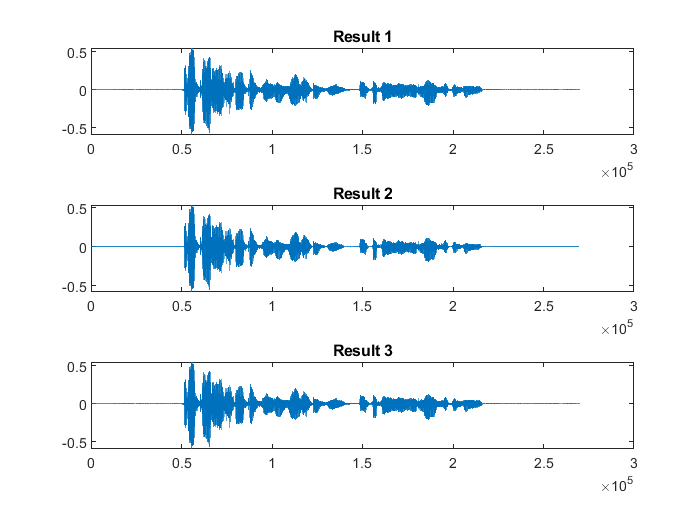

[x2,Fs] = audioread("my_audio_result_2.wav");
[x3,Fs] = audioread("my_audio_result_3.wav");
[x4,Fs] = audioread("my_audio_result_4.wav");

% Create Plots
subplot(3,1,1)
plot(x2);
title("Result 1")
subplot(3,1,2)
plot(x3);
title("Result 2")
subplot(3,1,3)
plot(x4);
title("Result 3")

Έτσι, στη συνέχεια ακούμε τους ήχους για να τους συγκρίνουμε και ηχητικά:

% Uncomment to listen audio result for specific technique
%soundsc(x2,44100);
%soundsc(x3,44100);
%soundsc(x4,44100);

### **Συμπεράσματα**

Δοκιμάζοντας τις τεχνικές και στο ηχογραφημένο αρχείο μας παρατηρούμε παρόμοια συμπεριφορά στα αποτελέσματα με πριν. Η τρίτη τεχνική φαίνεται και πάλι να έχει αρκετά υψηλό SNR, ενώ αυτήν τη φορά παρατηρείται αυξημένο SNR και από την τεχνική 4. Γενικά, δεν παρατηρούνται μεγάλες διαφορές στις τιμές των SNR σε αυτήν την περίπτωση, γεγονός που μπορεί να εξηγηθεί δεδομένου ότι το αρχικό αρχείο ήχου δεν είναι σχετικά "καθαρό" από θόρυβο και έτσι όλες οι τεχνικές επιτυγχάνουν μεγάλες τιμές SNR. Με άλλα λόγια, αν είχαμε ένα ηχητικό σήμα με πολύ θόρυβο ηθα ήταν πιο εύκολο να ξεχωρίσουμε την καλύτερη τεχνική αποθορυβοποίησης από ότι σε ένα που είναι απαλαγμένο σε μεγάλο βαθμό από θόρυβο.